N_NUMBERS = 5000;
m = 2^10;
X = randi(m, [1 55]);

for i=56:N_NUMBERS+55
    X(i) = mod(X(i-1) + X(i-2), m);
end

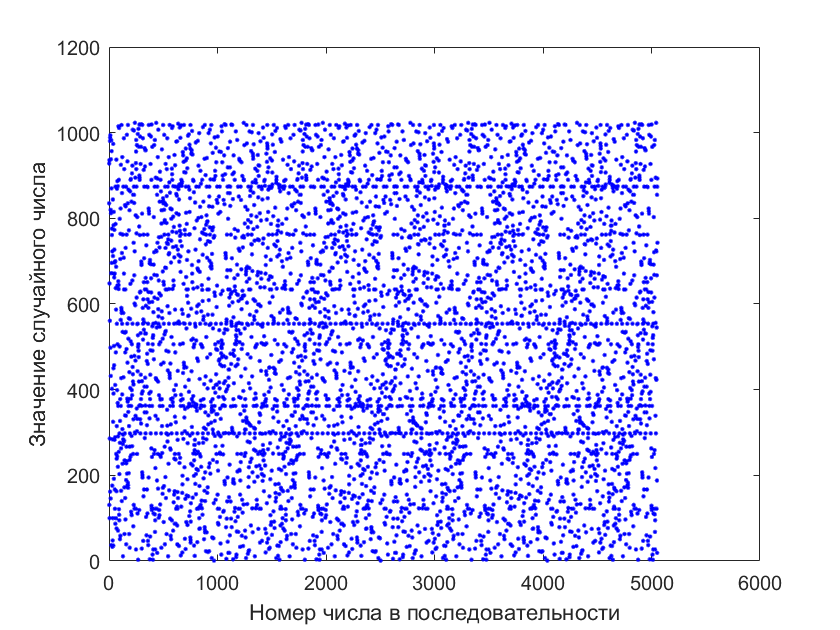

plot(X, 'b.')
xlabel("Номер числа в последовательности");
ylabel("Значение случайного числа");

alpha = 0.1;
nbins = 100;
edges = linspace(0,m,nbins+1);
E = N_NUMBERS/nbins*ones(nbins,1);

[h,p,stats] = chi2gof(X,'Expected',E,'Edges',edges);
%fprintf("Нулевую гипотезу о равномерном распределении нельяз отвергнуть при данном alpha: %d. (1 for true else 0)", p >= alpha);
fprintf("Распределение равномерно: %d", p >= alpha);

Распределение равномерно: 0

Двоичная система

N_NUMBERS = 5000;
m = 2;
X = randi(m-1, [1 3]);

for i=3:N_NUMBERS+3
    X(i) = mod(X(i-1) + X(i-2), m);
end

% количество единиц подряд
n_ones = 2;
true_prob = 0.5^n_ones

true_prob = 0.2500

c = 0;
for i=1:N_NUMBERS-n_ones
    if X(i:i+n_ones-1) == ones(n_ones,1)
        c = c + 1;
    end
end
real_prob = c/N_NUMBERS;

fprintf("Теор. вероятность появления %d единиц подряд: %f, фактическая: %f", n_ones, true_prob, real_prob)

Теор. вероятность появления 2 единиц подряд: 0.250000, фактическая: 0.333200